All Days


      Source          SS        df          MS               F              Prob>F    
    __________    __________    __    ______________    ____________    ______________

    {'Groups'}    3.7398e+06     6    {[6.2330e+05]}    {[ 30.9286]}    {[2.6516e-07]}
    {'Error' }    2.8214e+05    14    {[2.0153e+04]}    {0×0 double}    {0×0 double  }
    {'Total' }    4.0219e+06    20    {0×0 double  }    {0×0 double}    {0×0 double  }



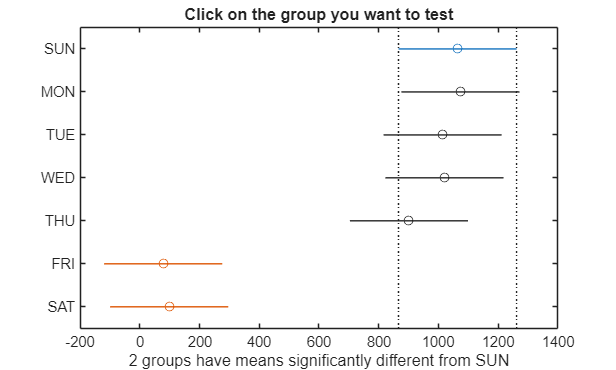

Middle of the Week


      Source          SS        df          MS               F             Prob>F   
    __________    __________    __    ______________    ____________    ____________

    {'Groups'}         56592     4    {[1.4148e+04]}    {[  0.5090]}    {[  0.7308]}
    {'Error' }    2.7798e+05    10    {[2.7798e+04]}    {0×0 double}    {0×0 double}
    {'Total' }    3.3457e+05    14    {0×0 double  }    {0×0 double}    {0×0 double}



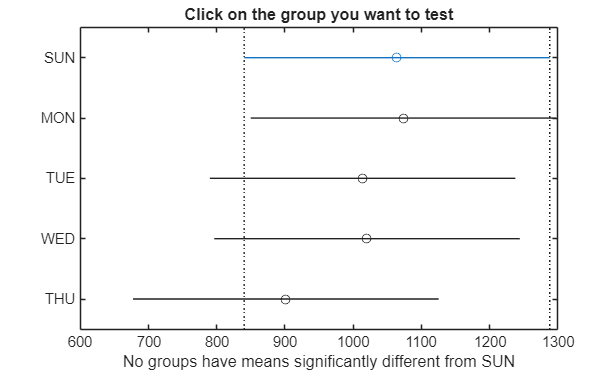

Quarter of the Year


      Source          SS        df          MS               F             Prob>F   
    __________    __________    __    ______________    ____________    ____________

    {'Groups'}    1.2631e+05     3    {[4.2103e+04]}    {[  0.7180]}    {[  0.5686]}
    {'Error' }    4.6913e+05     8    {[5.8642e+04]}    {0×0 double}    {0×0 double}
    {'Total' }    5.9544e+05    11    {0×0 double  }    {0×0 double}    {0×0 double}



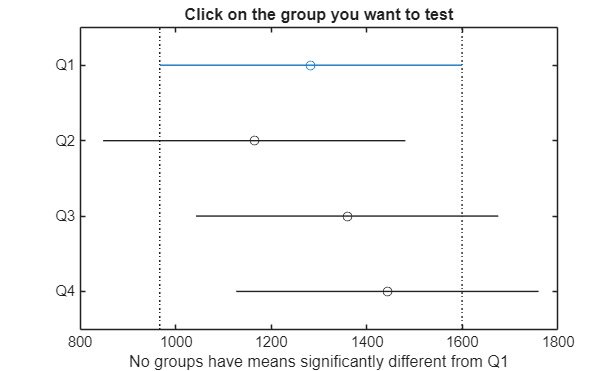

% A one-way ANOVA showed a highly significant effect of weekday on 
% GroupCount (F(6,14)=30.93, p<10⁻⁶), indicating substantial 
% differences in mean counts across weekdays, with weekday 
% explaining approximately 93% of the total variance.
%
% Once weekends are excluded, weekday activity levels are statistically
% indistinguishable; any apparent differences between Sunday-Thursday are
% likely due to random fluctuation rather than a systematic weekday effect.

anovaTest = ANOVATest('temp\processed_issues.csv');
tests = anovaTest.anovaTestForIssuesCountPerDay(2);
for i = 1:length(tests)
    figure
   t = tests{i};
   disp(t{1});
   table = cell2table(t{3}(2:end,:), 'VariableNames',t{3}(1,:));
   disp(table)
   multcompare(t{4});
   disp("====================================================================")
end

disp('Two-way ANOVA test')

Two-way ANOVA test


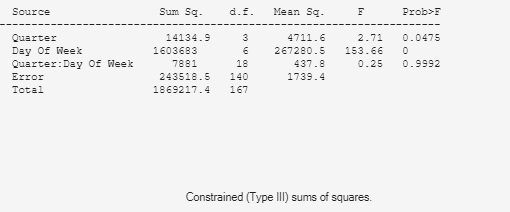

[T, p, tbl, stats] = anovaTest.anova2TestForIssuesCountPerQuarterAndDay(5);

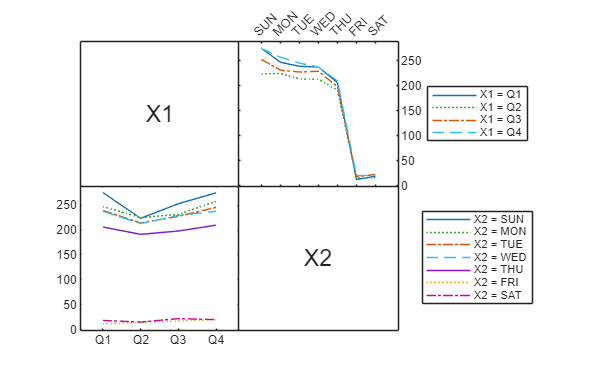

interactionplot(T.GroupCount, {T.quarter, T.day_of_week});

% A two-way ANOVA revealed a strong main effect of day of week on GroupCount
% (F(6,140)=153.66, p<10⁻⁵⁸), a weak but significant main effect of quarter
% (F(3,140)=2.71, p=0.048), and no significant interaction between quarter 
% and day of week (F(18,140)=0.25, p=0.999), indicating that weekday 
% patterns are consistent across quarters.


% | TestName                 | Factor              | df1 | df2 | F     | pValue | Significant | Notes                  |
% | ------------------------ | ------------------- | --- | --- | ----- | ------ | ----------- | ---------------------- |
% | One-way ANOVA (All Days) | DayOfWeek           | 6   | 14  | 30.93 | 2.6e-7 | true        | Weekends dominate      |
% | One-way ANOVA (Weekdays) | DayOfWeek           | 4   | 10  | 0.51  | 0.73   | false       | No weekday differences |
% | One-way ANOVA            | Quarter             | 3   | 8   | 0.72  | 0.57   | false       | No seasonal effect     |
% | Two-way ANOVA            | Quarter × DayOfWeek | 18  | 140 | 0.25  | 0.999  | false       | No interaction         |
